%read path
clear
clc

path = 'C:\Users\thamr\OneDrive\Desktop\finalMatlab\dataset-3a.xlsx';
Q1a = readmatrix(path,'Sheet','Q1A');
QHS1 = readmatrix(path,'Sheet','QH_S1');
QHS3 = readmatrix(path,'Sheet','QH_S3');

%เก็บข้อมูลลงในตัวแปร โดยทุก row แต่เลือก col
hData1 = QHS1(:,1);
qData1 = QHS1(:,2);
x = hData1';
y = qData1';

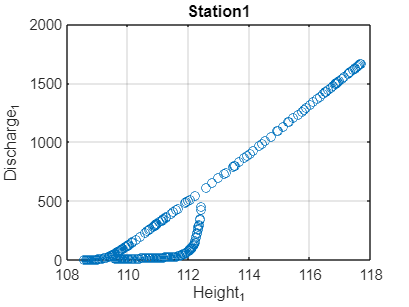

%พอตค่าที่เก็บไว้
hold off
plot(x,y,'o');
xlabel("Height_1")
ylabel("Discharge_1")
title("Station1")
grid on

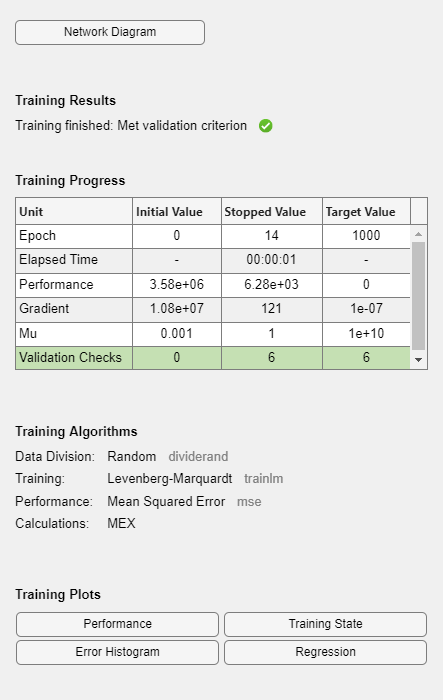

 %neural network model = md
    hLS = 30;
    net = feedforwardnet(hLS);
    mdl = train(net,x,y);

    nv = mdl(x);

%แสดงค่าพอตกับ model
hold on
plot(x,nv,'-','Color','r')
v = y;
% R squared 
R_squared = 1 - sum((v - nv).^2) / sum((v - mean(v)).^2);
% Mean Absolute Error (MAE) calculation
MAE = sum(abs(v - nv))/length(v);
% Mean Squared Error (MSE) calculation
MSE = (sum((v - nv).^2))/(length(v));
fprintf("R_squared : %.5f",R_squared);

R_squared : 0.97677

fprintf("MSE : %.4f",MSE);

MSE : 6520.2952

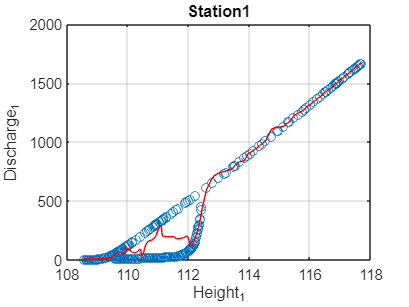

hold off

%คำนาย 60 วันจากค่าความสูงของระดับน้ำสถานีแรก
gUrl = 'http://192.168.1.143:5000/getdatawaterlv/Height_S1/60'; 
H1aTest = webread(gUrl); %Q1

Error using webread
The connection to URL 'http://192.168.1.143:5000/getdatawaterlv/Height_S1/60' timed out after 5.000 seconds. The reason is "Failed to connect to 192.168.1.143 port 5000 after 5111 ms: Timeout was reached". Perhaps the server is not responding or weboptions.Timeout needs to be set to a higher value.

H1aTest = (H1aTest.Height_S1);
input = H1aTest(56:end,:);
xlswrite(path,input,1,'B57');
H1aTest = H1aTest';
H1aTest = H1aTest(~isnan(H1aTest));
for i=1:length(H1aTest)
     predict = sim(mdl,H1aTest);
end
predict = predict(~isnan(predict));

%เขียนลง Sever
predictWrite = predict(1,56:end)';
xlswrite(path,predictWrite,1,'C57');

for i=1:length(predictWrite)
    data = predictWrite(i);
    url = 'http://192.168.1.143:5000/senddata/';
    url = [url,num2str(data)];
    response = webread(url); 
    fprintf("SendQ1 DONE %s %d\n",response,i)
end

%พอตกราฟค่าPredict เปรียบเทียบกับ ค่าจริงที่วัดได้พร้อมทำนายวันที่ 55-60
hold off
Q1a = readmatrix(path);
yTest = Q1a(:,3);
yTest = yTest(~isnan(yTest))';
xTest = Q1a(:,2);
xTest = xTest(~isnan(xTest))';
Day = 1:length(yTest);
plot(Day,yTest,'-',Color='b')
hold on
plot(Day(:,1:55),predict(:,1:55),'-',Color='r')
plot(Day(:,55:60),predict(:,55:60),'*',Color='r')
xlabel("Day")
ylabel("Discharge")
legend("Discharge_1","predictDischarge_1","Discharge(Day55-60)")
grid on

 nvAfter = predict(~isnan(predict));
 vAfter = yTest;
 % R squared 
 R_squared_test = 1 - sum((vAfter - nvAfter).^2) / sum((vAfter - mean(vAfter)).^2);
 % Mean Absolute Error (MAE) calculation
 MAE_test = sum(abs(vAfter - nvAfter))/length(vAfter);
 % Mean Squared Error (MSE) calculation
 MSE_test = (sum((vAfter - nvAfter).^2))/(length(vAfter));
 fprintf("R_squared predict : %.5f",R_squared_test);
 fprintf("MSE predict : %.4f",MSE_test);
 output = predictWrite';
 for i=1:5
    fprintf("Predict Q1 Form H1 Day %d %.2f\n",i+55,output(i));
end